This script attempts to replicate the conditions of experiments to see if simulation results are consistent.

In vivo data is generated in the script data/replicate_in_vivo_data.mlx and stored in the "ivd" data object.

%%Generic Setup



Trial 1:  Den Haan, Rose, Lynd, and van Zyl 2006 "Hydrolysis and fermentation of amorphous cellulose by recombinant Saccharomyces cerevisiae"

Experiment conditions:

-   -anaerobic

-   -substrate: amorphous phosphoric acid swollen cellulose (PASC)

-   -substrate recipe: 100ml YP-PASC medium supplemented with 0.01gl egosterol and 0.42g/l Tween 80

-   -cultures were inoculatred to approcimately 2x10^5 cells/ml 

organism details:

-   -origin strain: S.cerevisiae Y294 (ATCC 201160)

-   -endoglucanase cel7B from Trichoderma reesei

-   -beta-glucosidase BGL1 from Saccharomycopsis fubuligera

-   -NO exoglucanase

-   -plasmid expression under control of the yENO1 promoter

key observations:

-   -one unit of enzyme activity is defined as the amount of enzyme required to produce 1 umol of reducing sugar per minute under the assay conditions

-   -maximum endoglucanase activity in Y294[CEL5] was 0.30 U/mg*DCW

-   -maximum beta-glucosidase activity in Y294[CEL5] was 0.48 U/mg*DCW

-   -maximum cell density observed was 3.88e7 cells/mL

-   -ethanol production observed up to 1.0 g/L

assumptions

-   -due to lack of exoglucanase, assume the bottleneck in cellulose breakdown is endoglucanase activity

-   -endoglucanase and beta-glucosidase are produced at the same rate and have the same cost

%%Trial 1 (Anaerobic)

%current issue/blocker: conversion from cell dry weight <-> number of cells
%for the initial approach, don't worry about mapping the data exactly, normalize the curves to have the same maximum

%assuming a yeast cell weighs 5e-11 g, or 5e-8 mg 


%plot growth for all alphas
dat2 = sortrows(dat2,'alpha','descend');
%dat2 = dat2(ismember(dat2.alpha, exp([-8 -7 -6 -5 -5.4 -4 -3 -2])),:);
alphas = log(dat2.alpha);
colors = lines(90);
figure();
colormap(lines());
linestyles = {'-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' ...
    '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-'...
    '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-'...
    '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-'...
    '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-'...
    '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-'};
xmax = 250;
hold on;
for i = 1:length(alphas)
    r = dat2(i,:);
    plot(r.t{1}(1:xmax),r.biomass{1}(1:xmax),linestyles{i},'color',colors(i,:),'lineWidth',2);
end
%title('Biomass');
leg = legend(num2str(alphas),'location','eastoutside');
title(leg,'log(Alpha)');
xlabel('Time (h)');
ylabel('Biomass (g)');
hold off;

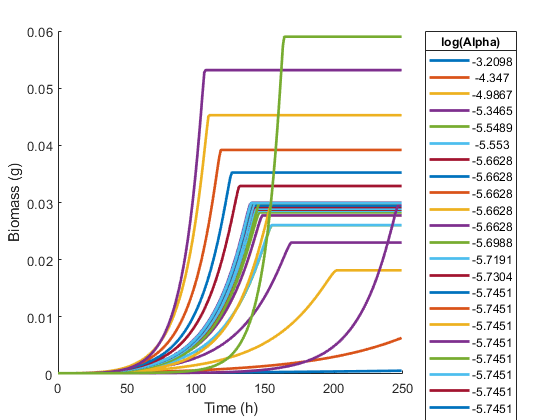


figure();
hold on;
for i = [3 4 5 6 7]
    r = dat2(dat2.alpha==(exp(-i)),:);
    idx = find(i == [2 3 4 5 6 7 8]);

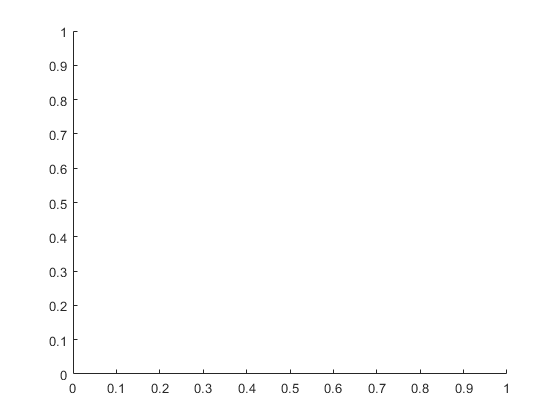

    plot(r.t{1}(1:xmax),r.biomass{1}(1:xmax),linestyles{idx},'color',colors(idx,:),'lineWidth',2);
end
plot(ivd.denhaan.ctdat + 90, ivd.denhaan.gdw,'--','linewidth',3);
%title('Biomass');

leg = legend([num2str([-2; -3; -4; -5; -6]); 'IV'],'location','eastoutside');
title(leg,'log(Alpha)');
xlabel('Time (h)');
ylabel('Biomass (g)');
hold off;

Index exceeds the number of array elements (0).


%surf plot of the above
t = dat2.t{1};
[X,Y] = meshgrid(alphas,t);
z = zeros(length(alphas),length(t));
for i = 1:length(alphas)
    for j = 1:length(t)
        rownum = dat2.alpha==exp(alphas(i));
        z(i,j) = dat2.biomass{rownum}(j);
    end
end
surf(X,Y,z');
xlabel('log(alpha)');
ylabel('Time (h)');
zlabel('Biomass(g)');
shading interp;

view([47.100 31.200])


Expected one output from a curly brace or dot indexing expression, but there were 0 results.

figure();
hold on;
for i = 1:length(alphas)
    r = dat2(alphas(i) == alphas,:);
    timestep = 1;
    plot(r.t{1}(1:end-1),r.biomass_delta{1}/timestep,linestyles{i},'color',colors(i,:),'lineWidth',2);
end
title('Growth Rate');
leg = legend(num2str(alphas),'location','eastoutside');
title(leg,'log(Alpha)');
hold off;


% figure();
% hold on;
% for i = [2 3 4 5 6 7 8]
%     r = dat2(dat2.alpha == exp(-i),:);
%     idx = find(i == [2 3 4 5 6 7 8]);
%     plot(r.t{1}(1:end-1),r.biomass_delta{1}./(r.biomass{1}(1:end-1) * r.layout{1}.params.timeStep),linestyles{idx},'color',colors(idx,:),'lineWidth',2);
% end
% title('Growth Rate (s^-^1)');
% leg = legend(num2str([-2; -3; -4; -5; -6; -7; -8]),'location','eastoutside');
% title(leg,'log(Alpha)');
% hold off;

%Find the fits
rs = zeros(length(alphas),1);
ssrs = zeros(length(alphas),1);

for i = 1:length(alphas)
    row = dat2(i,:);
    t_end = find(row.t{1} >= 250,1);
    bio = row.biomass{1}(1:t_end);
    t = row.t{1}(1:t_end);
    y_calc = bio\t;
    [pf,S] = polyfit(t,bio,3);
    [y_fit,delta] = polyval(pf,ivd.denhaan.ctdat,S);
%     hold on;
%     plot(t,bio,t,y_fit);
%     plot(t,y_fit+2*delta,'m--',t,y_fit-2*delta,'m--');
%     hold off;
    gdw = ivd.denhaan.gdw;
    res = ivd.denhaan.gdw - polyval(pf,ivd.denhaan.ctdat);
    %plot(res)
    r2 = 1 - sum((gdw - y_fit).^2)/sum((gdw - mean(y_fit)).^2);
    rs(i) = r2;
    ssrs(i) = sum((gdw - y_fit).^2);
    
end

rss_fun3_n = zeros(length(alphas),1);
rss_fun4_n = zeros(length(alphas),1);
rss_fun3_l = zeros(length(alphas),1);
rss_fun4_l = zeros(length(alphas),1);
r2_3_n = zeros(length(alphas),1);
r2_4_n = zeros(length(alphas),1);
r2_3_l = zeros(length(alphas),1);
r2_4_l = zeros(length(alphas),1);
v3n = zeros(length(alphas),1);
v4n = zeros(length(alphas),1);
v3l = zeros(length(alphas),1);
v4l = zeros(length(alphas),1);
k3n = zeros(length(alphas),1);
k4n = zeros(length(alphas),1);
k3l = zeros(length(alphas),1);
k4l = zeros(length(alphas),1);
rmse3n = zeros(length(alphas),1);
rmse4n = zeros(length(alphas),1);
rmse3l = zeros(length(alphas),1);
rmse4l = zeros(length(alphas),1);
rmse = zeros(length(alphas),1); %raw RMSE without a regression line
for i = 1:length(alphas)
    t_exp = ivd.denhaan.ctdat;
    b_exp = ivd.denhaan.gdw;
    t_sim = dat2.t{i};
    b_sim = dat2.biomass{i};
    b_sim = b_sim(ismember(t_sim,t_exp));
    logbexp = log10(b_exp);
    logbsim = log10(b_sim);
    summation = 0;
    n = length(logbexp);
    for j = 1:n
        val = logbsim(j) - logbexp(j);
        val = val^2;
        summation = summation + val;
    end
    rmse(i) = sqrt(summation/n);
end
for i = 1:length(alphas)
    [rss_fun3_n(i),r2_3_n(i),v3n(i),k3n(i),rmse3n(i)] = findFitQuality(ivd.denhaan.ctdat,ivd.denhaan.gdw,dat2.t{i},dat2.biomass{i},3);
    [rss_fun4_n(i),r2_4_n(i),v4n(i),k4n(i),rmse4n(i)] = findFitQuality(ivd.denhaan.ctdat,ivd.denhaan.gdw,dat2.t{i},dat2.biomass{i},4);
    [rss_fun3_l(i),r2_3_l(i),v3l(i),k3l(i),rmse3l(i)] = findFitQuality(ivd.denhaan.ctdat,ivd.denhaan.gdw,dat2.t{i},dat2.biomass{i},3,'log10');
    [rss_fun4_l(i),r2_4_l(i),v4l(i),k4l(i),rmse4l(i)] = findFitQuality(ivd.denhaan.ctdat,ivd.denhaan.gdw,dat2.t{i},dat2.biomass{i},4,'log10');
end

km = dat2.km_cel;
kcat = dat2.kcat_cel;
r2_3_n = abs(r2_3_n);
r2_4_n = abs(r2_4_n);
r2_3_l = abs(r2_3_l);
r2_4_l = abs(r2_4_l);
dat2.r2 = r2_3_l;
dat2.rmse_3_log = rmse3l;
dat2.rmse_4_log = rmse4l;
dat2.rmse_3 = rmse3n;
dat2.rmse_4 = rmse4n;
dat2.rmse = rmse;
fittab = table(alphas,rmse,rss_fun3_n,rss_fun4_n,rss_fun3_l,rss_fun4_l,r2_3_n,r2_4_n,r2_3_l,r2_4_l,v3n,v4n,v3l,v4l,k3n,k4n,k3l,k4l,rs,ssrs,km,kcat)
best = alphas(ssrs==min(ssrs))
best = alphas(r2_3_l==min(r2_3_l))
best = alphas(rmse == min(rmse))
best_arr = alphas([find((rss_fun3_n==min(rss_fun3_n))) find((rss_fun4_n==min(rss_fun4_n))) find((rss_fun3_l==min(rss_fun3_l))) find((rss_fun4_l==min(rss_fun4_l)))...
    find((r2_3_n==min(r2_3_n))) find(r2_4_n==min(r2_4_n)) find(r2_3_l==min(r2_3_l)) find(r2_4_l==min(r2_4_l)) ])
plotdata = horzcat(ssrs/max(ssrs),rss_fun3_n/max(rss_fun3_n),rss_fun4_n/max(rss_fun4_n),rss_fun3_l/max(rss_fun3_l)...
    ,rss_fun4_l/max(rss_fun4_l),r2_3_n/max(r2_3_n),r2_4_n/max(r2_4_n),r2_3_l/max(r2_3_l),r2_4_l/max(r2_4_l),...
    k3n/max(k3n),k4n/max(k4n),k3l/max(k3l),k4l/max(k4l),rmse/max(rmse));
plot(alphas,plotdata);
legend({'ssrs','rss_fun3_n','rss_fun4_n','rss_fun3_l','rss_fun4_l','r2_3_n','r2_4_n','r2_3_l','r2_4_l','k3n','k4n','k3l','k4l','rmse'});
plotdata = horzcat(rmse3n/max(rmse3n),rmse4n/max(rmse4n),rmse3l/max(rmse3l),rmse4l/max(rmse4l),rmse/max(rmse));
plot(alphas,plotdata);
legend({'rmse3n' 'rmse4n' 'rmse3l' 'rmse4l' 'rmse'})

%Analysis for a single alpha
data = ivd.denhaan;
best = alphas(find(rmse3l == min(rmse3l)))
best = alphas(find(rmse==min(rmse)))
a = exp(best);
row = dat2(dat2.alpha==a,:);
%v = row.layout{1}.models{1}.v;
[pf,S] = polyfit(row.t{1},row.biomass{1},3);

plot(row.t{1},row.biomass{1}/max(row.biomass{1}),data.ctdat,data.cydat/max(data.cydat),row.t{1},polyval(pf,row.t{1},S)/max(polyval(pf,row.t{1},S)),'lineWidth', 2)
leg = legend({'COMETS biomass' 'den Haan cell counts' 'Best Fit'},'location','best');
title('Growth (Normalized)')
xlabel('Time (h)')
ylabel('Biomass (percent max)')


%Denhaan biomass extrapolated from cell counts & max observed biomass reported as .27 g/L
%plot(row.t{1},row.biomass{1},data.ctdat,data.gdw,row.t{1},polyval(pf,row.t{1},S),'lineWidth', 2)
%leg = legend({'COMETS biomass' 'den Haan cell counts' 'Best Fit'},'location','best');
plot(row.t{1},row.biomass{1},data.ctdat,data.gdw,'lineWidth', 2)
leg = legend({'COMETS biomass' 'den Haan cell counts'},'location','best');
%title('Growth')
xlabel('Time (h)')
ylabel('Biomass (g)')

plot(row.t{1},log10(row.biomass{1}),data.ctdat,log10(data.gdw),row.t{1},log10(polyval(pf,row.t{1},S)),'lineWidth', 2)
leg = legend({'COMETS biomass' 'den Haan cell counts'},'location','best');
title('Growth')
xlabel('Time (h)')
ylabel('Log10(Biomass) (g)')

%Compare enzyme activity

%Convert units in in-vivo data to mmol
%NOTE: I SHOULD DO THIS THE OTHER WAY- CONVERT MMOL TO U
% ivdmmol = arrayfun(@(x) units2mmol(x,v.kcat_cel,v.km_cel,v.initcellulose),ivd.denhaan.units);
% plot(row.t{1},row.enzyme_amt{1},ivd.denhaan.units_t,ivdmmol);
v.spaceWidth = 100^(1/3);

simunits = arrayfun(@(x) mmol2units(x,v.kcat_cel,v.km_cel,v.initcellulose),row.enzyme_amt{1});
%simunits2 = arrayfun(@(x,y) mmol2units(x,v.kcat_cel,v.km_cel,y),row.enzyme_amt{1},row.cellulose_amt{1});
plot(row.t{1},simunits,ivd.denhaan.units_t,ivd.denhaan.units,'lineWidth', 2);
title('Enzyme Units by mmol Concentration')
xlabel('Time (h)')
ylabel('U')
legend({'Comets', 'Denhaan'})

plot(row.t{1},log(simunits),ivd.denhaan.units_t,log(ivd.denhaan.units),'lineWidth', 2);
title('Enzyme Units by mmol Concentration')
xlabel('Time (h)')
ylabel('Log(U)')
legend({'Comets', 'Denhaan'})

plot(row.t{1},simunits/max(simunits),ivd.denhaan.units_t,ivd.denhaan.units/max(ivd.denhaan.units),'lineWidth', 2);
title('Enzyme Units by mmol Concentration (Normalized)')
xlabel('Time (h)')
ylabel('U (percent max)')
legend({'Comets', 'Denhaan'})


simdelta = arrayfun(@(x) v2units(x,v.timestep),row.cellulose_delta{1} * v.glcpercellulose);
plot(row.t{1}(2:end),simdelta,ivd.denhaan.units_t,ivd.denhaan.units,'lineWidth', 2);
title('Enzyme Units by catalysis rate')
legend({'Comets', 'Denhaan'})
xlabel('Time (h)')
ylabel('U')

plot(row.t{1}(2:end),log(simdelta),ivd.denhaan.units_t,log(ivd.denhaan.units),'lineWidth', 2);
title('Enzyme Units by catalysis rate')
legend({'Comets', 'Denhaan'})
xlabel('Time (h)')
ylabel('Log(U)')

plot(row.t{1}(2:end),simdelta / max(simdelta),ivd.denhaan.units_t,ivd.denhaan.units/max(ivd.denhaan.units),'lineWidth', 2);
title('Enzyme Units by Catalysis Rate, Normalized')
legend({'Comets', 'Denhaan'})
xlabel('Time (h)')
ylabel('U (Percent max)')


%enzyme activity/biomass over time
c_act_perbio = (arrayfun(@(x) v2units(x,v.timestep),row.cellulose_delta{1} * v.glcpercellulose) ) ./ row.biomass{1}(1:end-1);
d_act_perbio = [0 (data.units([2 3 5 6]) ./ data.gdw(2:5))];
plot(row.t{1}(1:end-1),c_act_perbio,([0 24 48 72 92]),d_act_perbio,'lineWidth',2);
legend({'Comets' 'Denhaan'})
xlabel('Time (h)')
ylabel('U/GDW')
title('Enzyme Activity per Gram Biomass')

c_act_perbio = (arrayfun(@(x) v2units(x,v.timestep),row.cellulose_delta{1} * v.glcpercellulose) ) ./ row.biomass{1}(1:end-1);
d_act_perbio = [0 (data.units([2 3 5 6]) ./ data.gdw(2:5))];
plot(row.t{1}(1:end-1),log(c_act_perbio),([0 24 48 72 92]),log(d_act_perbio),'lineWidth',2);
legend({'Comets' 'Denhaan'})
xlabel('Time (h)')
ylabel('Log(U/GDW)')
title('Enzyme Activity per Gram Biomass')

c_act_perbio = (arrayfun(@(x) v2units(x,v.timestep),row.cellulose_delta{1} * v.glcpercellulose) ) ./ row.biomass{1}(1:end-1);
d_act_perbio = [0 (data.units([2 3 5 6]) ./ data.gdw(2:5))];
plot(row.t{1}(1:end-1),c_act_perbio/max(c_act_perbio),([0 24 48 72 92]),d_act_perbio/max(d_act_perbio),'lineWidth',2);
legend({'Comets' 'Denhaan'})
xlabel('Time (h)')
ylabel('U/GDW')
title('Enzyme Activity per Gram Biomass (Normalized)')


%ethanol
etohcon = row.etoh_amt{1};
etohweight = etohcon * .04607; %46.07g/mole = .04607 grams per millimole
plot(row.t{1},etohweight,data.eptdat,data.etohdat,'lineWidth',2)
legend({'Comets', 'Denhaan'})
title('Ethanol Yield')
xlabel('Time (h)')
ylabel('Yield (g)')

plot(row.t{1},etohweight/max(etohweight),data.eptdat,data.etohdat/max(data.etohdat),'lineWidth',2)
legend({'Comets', 'Denhaan'})
title('Ethanol Yield (Normalized)')
xlabel('Time (h)')
ylabel('Yield (% Max)')

plot(row.t{1},row.cellulose_amt{1},row.t{1},row.glc_amt{1},'LineWidth',2);
legend({'Cellulose' 'Glucose'});
title('Carbohydrate Concentrations');

plot(row.t{1},row.cellulose_amt{1}/max(row.cellulose_amt{1}),row.t{1},row.glc_amt{1}/max(row.glc_amt{1}),'LineWidth',2);
legend({'Cellulose' 'Glucose'});
title('Carbohydrate Concentrations, Normalized');


**%Plot data for varying kinetics**

%data prep
dat2_kin.max_biomass = cellfun(@(x) max(x),dat2_kin.biomass);
[nrows, ncols] = size(dat2_kin);
for i = 1:nrows
    row = dat2_kin(i,:);
    t_end = find(row.t{1} >= 250,1);
    bio = row.biomass{1}(1:t_end);
    t = row.t{1}(1:t_end);
    y_calc = bio\t;
    [pf,S] = polyfit(t,bio,3);
    [y_fit,delta] = polyval(pf,ivd.denhaan.ctdat,S);
%     hold on;
%     plot(t,bio,t,y_fit);
%     plot(t,y_fit+2*delta,'m--',t,y_fit-2*delta,'m--');
%     hold off;
    gdw = ivd.denhaan.gdw;
    res = ivd.denhaan.gdw - polyval(pf,ivd.denhaan.ctdat);
    %plot(res)
    r2 = 1 - sum((gdw - y_fit).^2)/sum((gdw - mean(y_fit)).^2);
    dat2_kin.rs(i) = r2;
    dat2_kin.ssrs(i) = sum((gdw - y_fit).^2);
end

rss_fun3_n = zeros(nrows,1);
rss_fun4_n = zeros(nrows,1);
rss_fun3_l = zeros(nrows,1);
rss_fun4_l = zeros(nrows,1);
r2_3_n = zeros(nrows,1);
r2_4_n = zeros(nrows,1);
r2_3_l = zeros(nrows,1);
r2_4_l = zeros(nrows,1);
v3n = zeros(nrows,1);
v4n = zeros(nrows,1);
v3l = zeros(nrows,1);
v4l = zeros(nrows,1);
k3n = zeros(nrows,1);
k4n = zeros(nrows,1);
k3l = zeros(nrows,1);
k4l = zeros(nrows,1);
rmse3n = zeros(nrows,1);
rmse4n = zeros(nrows,1);
rmse3l = zeros(nrows,1);
rmse4l = zeros(nrows,1);
rmse = zeros(nrows,1); %raw RMSE without a regression line
for i = 1:nrows
    [rss_fun3_n(i),r2_3_n(i),v3n(i),k3n(i),rmse3n(i)] = findFitQuality(ivd.denhaan.ctdat,ivd.denhaan.gdw,dat2_kin.t{i},dat2_kin.biomass{i},3);
    [rss_fun4_n(i),r2_4_n(i),v4n(i),k4n(i),rmse4n(i)] = findFitQuality(ivd.denhaan.ctdat,ivd.denhaan.gdw,dat2_kin.t{i},dat2_kin.biomass{i},4);
    [rss_fun3_l(i),r2_3_l(i),v3l(i),k3l(i),rmse3l(i)] = findFitQuality(ivd.denhaan.ctdat,ivd.denhaan.gdw,dat2_kin.t{i},dat2_kin.biomass{i},3,'log10');
    [rss_fun4_l(i),r2_4_l(i),v4l(i),k4l(i),rmse4l(i)] = findFitQuality(ivd.denhaan.ctdat,ivd.denhaan.gdw,dat2_kin.t{i},dat2_kin.biomass{i},4,'log10');
end
for i = 1:nrows
    t_exp = ivd.denhaan.ctdat;
    b_exp = ivd.denhaan.gdw;
    t_sim = dat2_kin.t{i};
    b_sim = dat2_kin.biomass{i};
    b_sim = b_sim(ismember(t_sim,t_exp));
    logbexp = log10(b_exp);
    logbsim = log10(b_sim);
    summation = 0;
    n = length(logbexp);
    for j = 1:n
        val = logbsim(j) - logbexp(j);
        val = val^2;
        summation = summation + val;
    end
    rmse(i) = sqrt(summation/n);
end



km = dat2_kin.km_cel;
kcat = dat2_kin.kcat_cel;
r2_3_n = abs(r2_3_n);
r2_4_n = abs(r2_4_n);
r2_3_l = abs(r2_3_l);
r2_4_l = abs(r2_4_l);
rs = dat2_kin.rs;
ssrs = dat2_kin.ssrs;
dat2_kin.r2 = r2_3_l;
dat2_kin.rmse_3_log = rmse3l;
dat2_kin.rmse_4_log = rmse4l;
dat2_kin.rmse_3 = rmse3n;
dat2_kin.rmse_4 = rmse4n;
dat2_kin.rmse = rmse;
fittab = table(rmse,rss_fun3_n,rss_fun4_n,rss_fun3_l,rss_fun4_l,r2_3_n,r2_4_n,r2_3_l,r2_4_l,v3n,v4n,v3l,v4l,k3n,k4n,k3l,k4l,rs,ssrs,km,kcat)
rownums = 1:nrows;
best = rownums(ssrs==min(ssrs))
best = rownums(rmse3l==min(rmse3l))
best = rownums(rmse3n==min(rmse3n))
best = rownums(rmse==min(rmse))
isbest = [(rmse==min(rmse)) ((rss_fun3_n==min(rss_fun3_n))) ((rss_fun4_n==min(rss_fun4_n))) ((rss_fun3_l==min(rss_fun3_l))) ((rss_fun4_l==min(rss_fun4_l)))...

fittab = 61×21 table
     rmse      rss_fun3_n    rss_fun4_n    rss_fun3_l    rss_fun4_l    r2_3_n     r2_4_n     r2_3_l     r2_4_l     v3n    v4n    v3l    v4l    k3n    k4n    k3l    k4l       rs           ssrs           km         kcat 
    _______    __________    __________    __________    __________    _______    _______    _______    _______    ___    ___    ___    ___    ___    ___

    ((r2_3_n==min(r2_3_n))) (r2_4_n==min(r2_4_n)) (r2_3_l==min(r2_3_l)) (r2_4_l==min(r2_4_l)) (rs==min(rs)) (ssrs==min(ssrs))]
% bestrowidxs = [find((rss_fun3_n==min(rss_fun3_n))) find((rss_fun4_n==min(rss_fun4_n))) find((rss_fun3_l==min(rss_fun3_l))) find((rss_fun4_l==min(rss_fun4_l)))...

best = 28

%     find((r2_3_n==min(r2_3_n))) find(r2_4_n==min(r2_4_n)) find(r2_3_l==min(r2_3_l)) find(r2_4_l==min(r2_4_l)) ]

best = 58

% best_arr = rownums(bestrowidxs)

best = 58

% plotdata = horzcat(ssrs/max(ssrs),rss_fun3_n/max(rss_fun3_n),rss_fun4_n/max(rss_fun4_n),rss_fun3_l/max(rss_fun3_l)...

best = 57

%     ,rss_fun4_l/max(rss_fun4_l),r2_3_n/max(r2_3_n),r2_4_n/max(r2_4_n),r2_3_l/max(r2_3_l),r2_4_l/max(r2_4_l),...
%     k3n/max(k3n),k4n/max(k4n),k3l/max(k3l),k4l/max(k4l));

isbest = 61×11 logical array
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0


% [X,Y] = meshgrid(km,kcat);
% surf(X,Y,plotdata);
% legend({'ssrs','rss_fun3_n','rss_fun4_n','rss_fun3_l','rss_fun4_l','r2_3_n','r2_4_n','r2_3_l','r2_4_l','k3n','k4n','k3l','k4l'});
besttable = table(dat2_kin.alpha,km,kcat,isbest(:,1),isbest(:,2),isbest(:,3),isbest(:,4),isbest(:,5),isbest(:,6),isbest(:,7),isbest(:,8),isbest(:,9),isbest(:,10),isbest(:,11));
besttable.Properties.VariableNames = {'alpha','km','kcat','rmse','rss_fun3_n','rss_fun4_n','rss_fun3_l','rss_fun4_l','r2_3_n','r2_4_n','r2_3_l','r2_4_l','rs','ssrs'}

%keep the best alpha
bestrow = find(ssrs==min(ssrs))
bestrow = find(dat2_kin.rs == min(dat2_kin.rs))

besttable = 61×14 table
      alpha          km         kcat     rmse     rss_fun3_n    rss_fun4_n    rss_fun3_l    rss_fun4_l    r2_3_n    r2_4_n    r2_3_l    r2_4_l     rs      ssrs 
    _________    __________    ______    _____    __________    __________    __________    __________    ______    ______    ______    ______    _____    _____

     0.040363    0.00041755    77.454    false      false         false         false         false       false     false     false     false     false    false
     0.012945   

bestrow = find(r2_3_l == min(r2_3_l))
bestrow = find(rmse3l == min(rmse3l))
bestrow = find(rmse3n == min(rmse3n))

bestrow = 28

bestrow = find(rmse3l == min(rmse3l))

bestrow = 60

bestrow = find(rmse == min(rmse))

bestrow = 31

bestalpha = besttable.alpha(bestrow(1))

bestrow = 58

log(bestalpha)

bestrow = 58

bestkm = besttable.km(bestrow)

bestrow = 58

log10bestkm = log10(bestkm)

bestrow = 57

bestkcat = besttable.kcat(bestrow)

bestalpha = 0.0021

log10bestkcat = log10(bestkcat)

ans = -6.1561

dat2_kin_singleA = dat2_kin(dat2_kin.alpha == bestalpha,:);

bestkm = 2.8263e-04

log10bestkm = -3.5488

%remove redundant rows

bestkcat = 84.4794

dat2_kin_singleA = sortrows(dat2_kin_singleA,{'alpha','km_cel','kcat_cel'});

log10bestkcat = 1.9268

temp = dat2_kin_singleA(1,:);
[nrows,ncols] = size(dat2_kin_singleA);
for i = 2:nrows
    lastrow = temp(end,:);
    nextrow = dat2_kin_singleA(i,:);
    if (nextrow.alpha ~= lastrow.alpha || nextrow.km_cel ~= lastrow.km_cel ||...
            nextrow.kcat_cel ~= lastrow.kcat_cel)
        temp = vertcat(temp,nextrow);
    end
end
dat2_kin_best = temp;

%make a surf plot for R-squared over log change in vmax and km
bestrow = find(dat2_kin_best.r2 == max(dat2_kin_best.r2))
bestrow = find(dat2_kin_best.rmse_3_log == min(dat2_kin_best.rmse_3_log))
bestrow = find(dat2_kin_best.rmse == min(dat2_kin_best.rmse))
%bestrow = find(dat2_kin_best.rmse_3 == min(dat2_kin_best.rmse_3))

bestrow = 1

bestrow = bestrow(1);

bestrow = 1

km_def = v_default.km_cel;

bestrow = 1

kcat_def = v_default.kcat_cel;
x = dat2_kin_best.kcat_cel;
x = unique(x);
y = dat2_kin_best.km_cel;
y = unique(y);
z = nan(length(x),length(y));
for i = 1:length(x)
    for j = 1:length(y)
        zt = dat2_kin_best.rmse_3_log(dat2_kin_best.kcat_cel==x(i) & dat2_kin_best.km_cel==y(j));
        if (~isempty(zt))
            z(i,j) = zt;
        end
    end
end
x = log10(x);
y = log10(y);
[X,Y] = meshgrid(x,y);
surf(X,Y,z');
xlabel('log10 Kcat');
ylabel('log10 KM');
zlabel('RMSE (log10 Z)');

Error using surf (line 71)
Z must be a matrix, not a scalar or vector.


%mark the peak
hold on;
plot3(log10(dat2_kin_best.kcat_cel),log10(dat2_kin_best.km_cel),dat2_kin_best.rmse_3_log,'.r','markersize',10);
plot3(log10(dat2_kin_best.kcat_cel(bestrow)),log10(dat2_kin_best.km_cel(bestrow)),dat2_kin_best.rmse_3_log(bestrow),'.b','markersize',20);
hold off;

view([251 31])


x = dat2_kin_best.kcat_cel;
x = unique(x);
y = dat2_kin_best.km_cel;
y = unique(y);
[X,Y] = meshgrid(x,y);
surf(X,Y,z');
xlabel('Kcat');
ylabel('KM');
zlabel('RMSE (log10 Z)');
hold on;
plot3((dat2_kin_best.kcat_cel),(dat2_kin_best.km_cel),dat2_kin_best.rmse_3_log,'.r','markersize',10);
plot3((dat2_kin_best.kcat_cel(bestrow)),(dat2_kin_best.km_cel(bestrow)),dat2_kin_best.rmse_3_log(bestrow),'.b','markersize',20);
hold off;
view([-52 21.600])


%3d scatter of data at all alphas
x = dat2_kin.kcat_cel;
x = unique(x);
y = dat2_kin.km_cel;
y = unique(y);
z = nan(length(x),length(y));
for i = 1:length(x)
    for j = 1:length(y)
        zt = dat2_kin_best.rmse_3_log(dat2_kin_best.kcat_cel==x(i) & dat2_kin_best.km_cel==y(j));
        if (~isempty(zt))
            z(i,j) = zt;
        end
    end
end
x = log10(x);
y = log10(y);
[X,Y] = meshgrid(x,y);
surf(X,Y,z');
xlabel('log10 Kcat');
ylabel('log10 KM');
zlabel('RMSE (log10 Z)');

alphas = unique(dat2_kin.alpha);
colors = jet(length(unique(dat2_kin.alpha)));
colormat = zeros(length(dat2_kin.alpha),3);
for i = 1:length(dat2_kin.alpha)
    colormat(i,:) = colors(logical(dat2_kin.alpha(i)==alphas),:);
end

%mark the peak
hold on;
plot3(log10(dat2_kin.kcat_cel),log10(dat2_kin.km_cel),dat2_kin.rmse_3_log,'.','markersize',10);
hold off;
% c = colorbar('eastoutside');
% c.Label.String = 'Alpha';

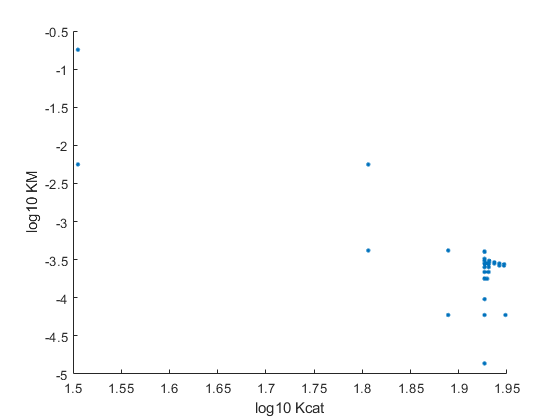

%time series plot of the best fit
data = ivd.denhaan;

bestrow = find(dat2_kin_best.rmse_3==min(dat2_kin_best.rmse_3));
row = dat2_kin_best(bestrow(1),:);
bestr2 = max(dat2_kin_best.r2)
bestrmse_3 = min(dat2_kin_best.rmse_3)
bestkm = row.km_cel
bestkcat = row.kcat_cel
%v = row.layout{1}.models{1}.v;
[pf,S] = polyfit(row.t{1},row.biomass{1},3);

bestr2 = 0.6113

bestrmse_3 = 0.4333

plot(row.t{1},row.biomass{1}/max(row.biomass{1}),data.ctdat,data.cydat/max(data.cydat),row.t{1},polyval(pf,row.t{1},S)/max(polyval(pf,row.t{1},S)),'lineWidth', 2)

bestkm = 2.8263e-04

leg = legend({'COMETS biomass' 'den Haan cell counts' 'Best Fit'},'location','best');

bestkcat = 84.4794

title('Growth (Normalized)')
xlabel('Time (h)')

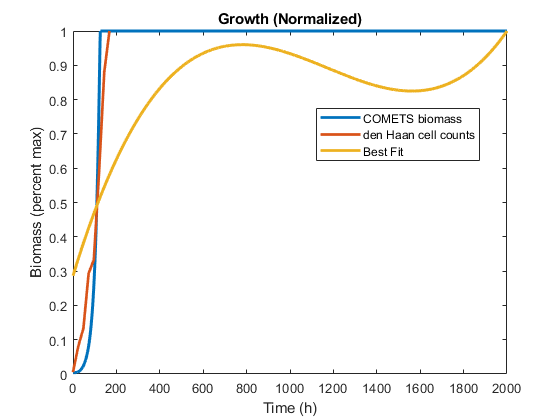

ylabel('Biomass (percent max)')


%Denhaan biomass extrapolated from cell counts & max observed biomass reported as .27 g/L
plot(row.t{1},row.biomass{1},data.ctdat,data.gdw,row.t{1},polyval(pf,row.t{1},S),'lineWidth', 2)
leg = legend({'COMETS biomass' 'den Haan cell counts' 'Best Fit'},'location','best');

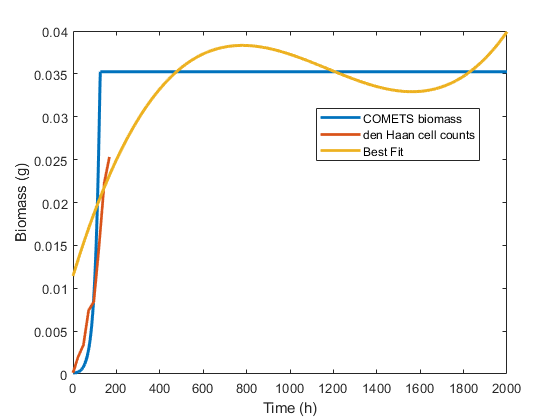

%title('Growth')
xlabel('Time (h)')
ylabel('Biomass (g)')

plot(row.t{1},log10(row.biomass{1}),data.ctdat,log10(data.gdw),row.t{1},log10(polyval(pf,row.t{1},S)),'lineWidth', 2)
leg = legend({'COMETS biomass' 'den Haan cell counts' 'Best Fit'},'location','best');
%title('Growth')
xlabel('Time (h)')

ylabel('Log10 Biomass (g)')


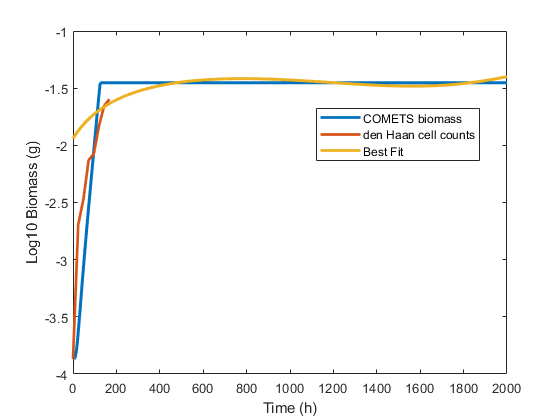

%Basic timeseries for the best run
row = dat2_kin(dat2_kin.rmse == min(dat2_kin.rmse),:);
t = row.t{1};
glc = row.glc_amt{1};

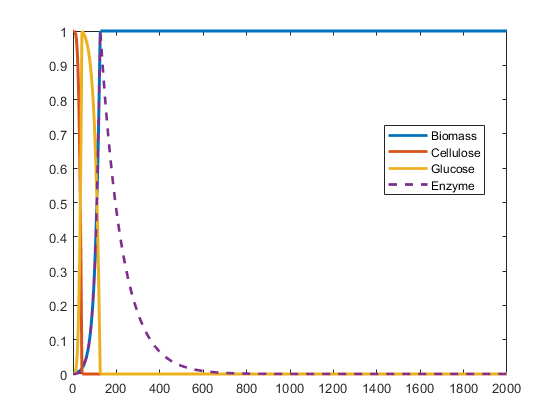

glc = glc/max(glc);
cel = row.cellulose_amt{1};
cel = cel/max(cel);
bio = row.biomass{1};
bio = bio/max(bio);
enz = row.enzyme_amt{1};
enz = enz/max(enz);
plot(t,bio,'-',t,cel,'-',t,glc,'-',t,enz,'--','linewidth',2);
legend({'Biomass' 'Cellulose' 'Glucose' 'Enzyme'},'location','best');


plot(t,bio,'-',t,cel,'-',t,glc,'-',t,enz,'--','linewidth',2);
legend({'Biomass' 'Cellulose' 'Glucose' 'Enzyme'},'location','best');
a = gca();
set(a,'YScale','log');

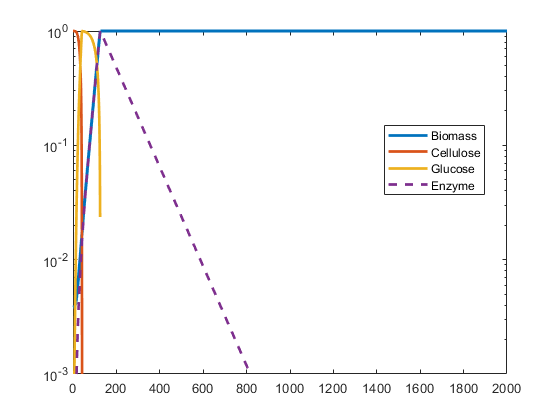

ylim([1e-3,1]);

plot(t,row.biomass{1},'-',t,row.cellulose_amt{1},'-',t,row.glc_amt{1},'-',t,row.enzyme_amt{1},'-','linewidth',2);
legend({'Biomass' 'Cellulose' 'Glucose' 'Enzyme'},'location','best');
a = gca();
set(a,'YScale','log');
ylim([1e-6,10]);

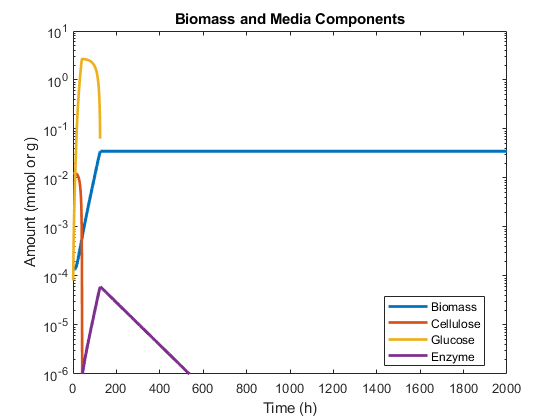

ylabel('Amount (mmol or g)');
xlabel('Time (h)');
title('Biomass and Media Components')
